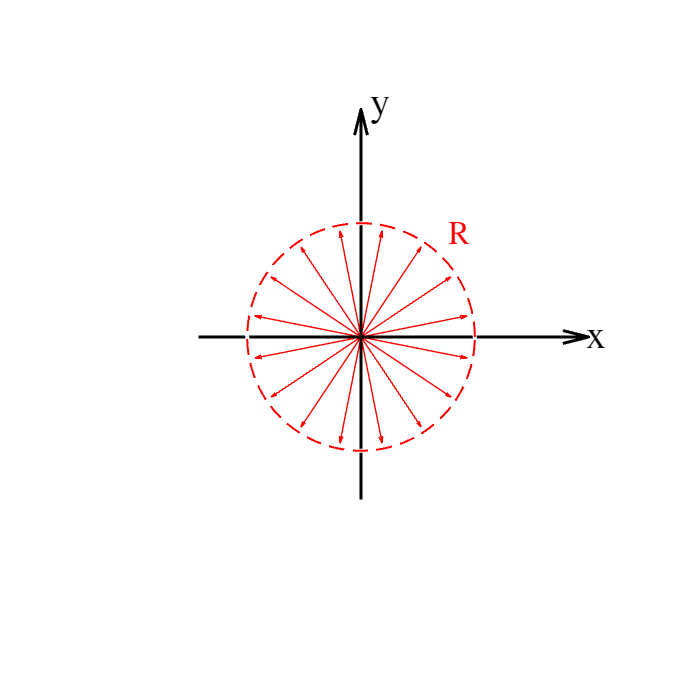

clear
clc

N = 16;
r = 2;

fg = figure('Position',[0,0,600,600]);
hold on
for i = 1:N
    th = i * 360 / N + 180/N;
    x = r * cosd(th);
    y = r * sind(th);
    quiver(0,0,x,y,1,'r','filled');
end
quiver(-3,0,8,0,'k','filled','LineWidth',1.5)
quiver(0,-3,0,8,'k','filled','LineWidth',1.5)

viscircles([0,0],r*1.05,'LineWidth',1,'LineStyle','--');
text(1.1*r*cosd(45),1.1*r*sind(45),"R", ...
    'HorizontalAlignment','left', ...
    'VerticalAlignment','bottom', ...
    'Color','r', ...
    'Interpreter','latex', ...
    'FontSize',16)

text(4.6,0.05,"x", ...
    'Interpreter','latex', ...
    'HorizontalAlignment','right' ...
    ,'FontSize',20)
text(0.1,4.8,"y", ...
    'Interpreter','latex', ...
    'VerticalAlignment','top' ...
    ,'FontSize',20)

hold off
axis equal
axis off
xticks([]);
yticks([]);
box off
xlim([-5,5])
ylim([-5 5])

saveas(fg,"analyticalSolLaplace","svg");